# **IronFork : Cinématique inverse**

## Cinématique inverse 

Mise en place du solveur

gik = generalizedInverseKinematics('RigidBodyTree', IronFork, ...
    'ConstraintInputs', {'position','aiming','joint'})

gik =   generalizedInverseKinematics with properties:

      NumConstraints: 3
    ConstraintInputs: {'position'  'aiming'  'joint'}
       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


Mise en place des contraintes 

positionVoulue = [arc(1,1) arc(2,1) arc(3,1)];

limiteAngle = constraintJointBounds(IronFork);
limiteAngle.Bounds= [deg2rad(-5) deg2rad(190);
                     deg2rad(-30)   deg2rad(120);
                     deg2rad(0)   deg2rad(180);
                     deg2rad(-125) deg2rad(45)];

horizontalConst = constraintAiming("cuillereBout");
horizontalConst.TargetPoint= [0 0 10000];

posConst = constraintPositionTarget("cuillereBout");
posConst.TargetPosition = positionVoulue;


Calcul d'une solution:

tic
[q,solutionInfo] = gik(q0,posConst,horizontalConst,limiteAngle);
toc

Elapsed time is 0.561035 seconds.


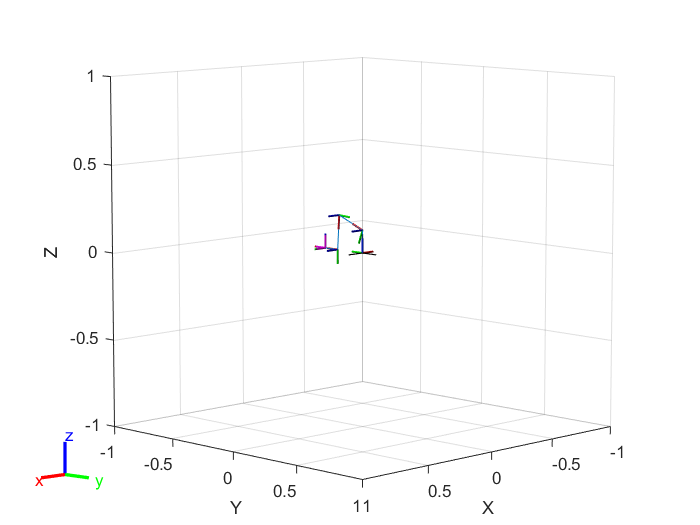


figure;
show(IronFork,q);


%alpha1=q(1).JointPosition;


Calcul de cinématique inverse pour la trajectoire :

longTraj=size(arc(1,1:213));
p=q0;
listeConfiguration=zeros(4,longTraj(2));
listeConfigurationQ=cell([0,longTraj(2)]);



for n=1:longTraj(2)
    
    positionVoulue = [arc(1,n) arc(2,n) arc(3,n)];
    posConst.TargetPosition = positionVoulue;
    
    [q,solutionInfo] = gik(p,posConst,horizontalConst,limiteAngle);
    solutionInfo.Status;
    p=q;
    listeConfigurationQ(n)={q};
    
    for i=1:4
        listeConfiguration(i,n)=rad2deg(q(i).JointPosition);
    end
    
end

Animation du Robot

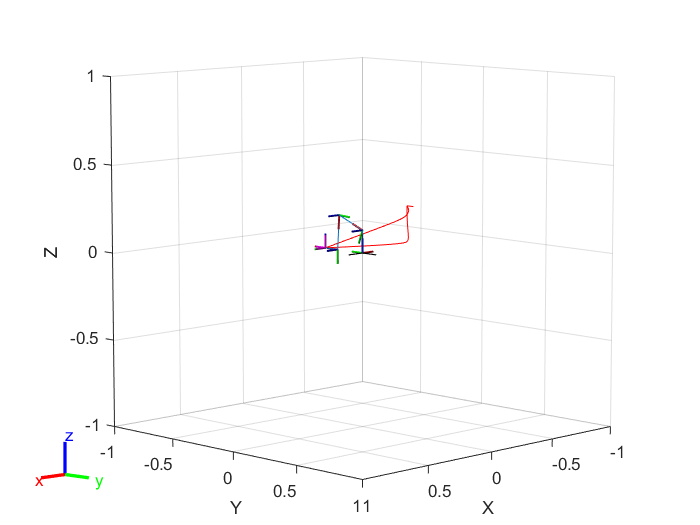

figure;

for n=1:longTraj(2)
    
    show(IronFork,listeConfigurationQ{1,n});
    hold on;
    
    plot3(arc(1,1:n),arc(2,1:n),arc(3,1:n),"-r");
    hold off;
    
    pause(0.02);
    
end

%viztree = interactiveRigidBodyTree(IronFork)

## CInématique pour le mouvement de pelletage

gik2 = generalizedInverseKinematics('RigidBodyTree', IronFork, ...
    'ConstraintInputs', {'pose', 'joint'})

gik2 =   generalizedInverseKinematics with properties:

      NumConstraints: 2
    ConstraintInputs: {'pose'  'joint'}
       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


Contrainte de posture

pelletageConst = constraintPoseTarget("cuillereBout");

%mise en place de la matrice de transformation test


Mpose = trvec2tform([posePelletage(1,1) ...
    posePelletage(2,1) posePelletage(3,1)])*eul2tform([-pi/2, deg2rad(20), 0]);


pelletageConst.TargetTransform = Mpose ; 

Résolution : 

p=q0;
configurationPelletage=zeros(4,length(anglePelletage));
configurationPelletageQ=cell([0,length(anglePelletage)]);

for i=1:length(anglePelletage)

    %mise en place de la matrice de transformation 

    Mpose = trvec2tform([posePelletage(1,i) posePelletage(2,i) posePelletage(3,i)])*eul2tform([-pi/2, deg2rad(anglePelletage(1,i)), 0]);

    pelletageConst.TargetTransform = Mpose ; 
    
    [q,solutionInfo] = gik2(p,pelletageConst,limiteAngle);
    solutionInfo.Status;
    p=q;
    configurationPelletageQ(i)={q};
    
    for n=1:4
        configurationPelletage(n,i)=rad2deg(q(n).JointPosition);
    end
end

Animation

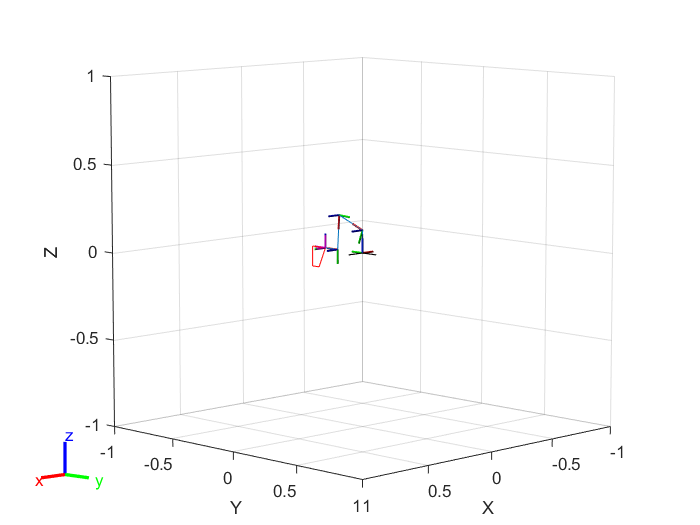

figure;

for n=1:length(anglePelletage)
    
    show(IronFork,configurationPelletageQ{1,n});
    hold on;
    
    plot3(posePelletage(1,1:n),posePelletage(2,1:n),posePelletage(3,1:n),"-r");
    hold off;
    
    pause(0.001);
    
end

configurationCycle=[listeConfiguration configurationPelletage];
configurationCycleQ=[listeConfigurationQ configurationPelletageQ];

Animation Cycle

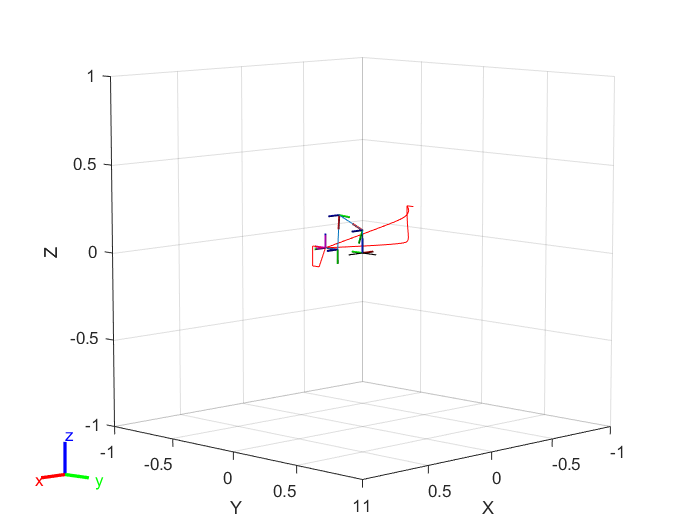

figure;

for n=1:length(configurationCycle)
    
    show(IronFork,configurationCycleQ{1,n});
    hold on;
    
    plot3(arc(1,1:n),arc(2,1:n),arc(3,1:n),"-r");
    hold off;
    
    pause(0.001);
    
end